# Complex Exponential Function

This live script investigates the complex exponential functions $y=Ae^{i\omega_0 n}$ and  $y_2=Ae^{-i\omega_0 n}$ sampled at the sampling rate $fs$. First, let's define some useful variables:

A = 1;  % amplitude
f = 100; % linear frequency in Hz (s^-1)
fs = 8000; % sampling frequency in Hz
f0 = f/fs; % normalized lin. frequency
omega = 2*pi*f; % angular frequency omega
omega0 = 2*pi*f0;  % normalized angular frequency

Now, let's have a look what the two functions look like in the z-plane.

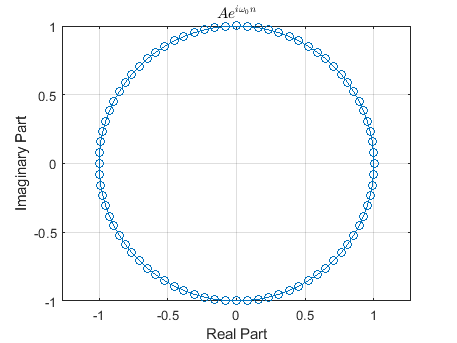

N =80;
n = 0:N;  % n time samples

Y = A*exp(1i*omega0*n);
plot(real(Y),imag(Y),'-o');
xlabel("Real Part");
ylabel("Imaginary Part");
title('$Ae^{i\omega_0 n}$',"Interpreter","latex");
grid;
axis equal;

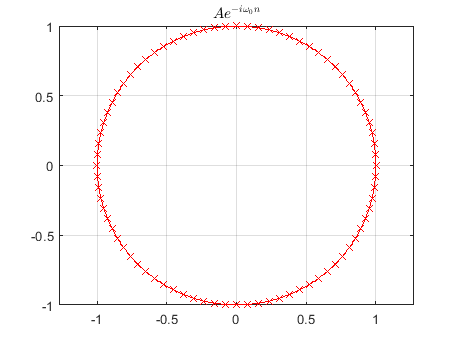


Y2 = A*exp(-1i*omega0*n);
plot(real(Y2),imag(Y2),'r-x');
axis equal;
title('$Ae^{-i\omega_0 n}$',"Interpreter","latex");
grid;

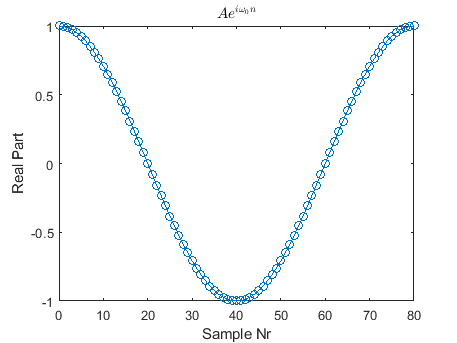


plot(n,real(Y),'-o');  % real part of \exp{i\omega_0*n}
xlabel("Sample Nr");
ylabel("Real Part");
title('$Ae^{i\omega_0 n}$',"Interpreter","latex");

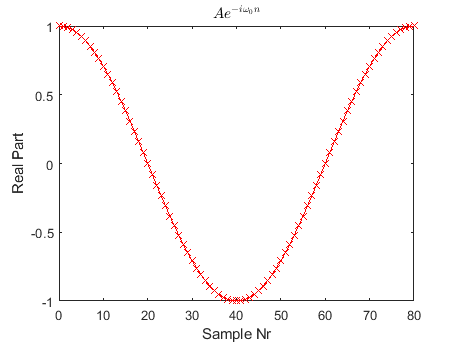


plot(n,real(Y2),'r-x'); % real part of \exp{-i\omega_0*n}
xlabel("Sample Nr");
ylabel("Real Part");
title('$Ae^{-i\omega_0 n}$',"Interpreter","latex");

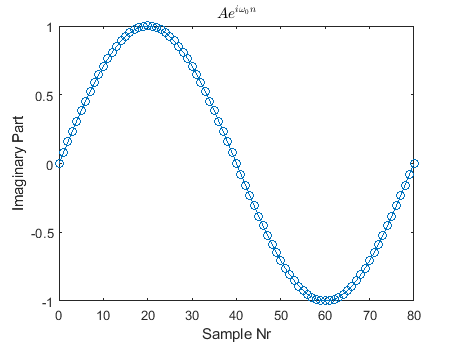


plot(n,imag(Y),'-o');  % imaginary part of \exp{i\omega_0*n}
xlabel("Sample Nr");
ylabel("Imaginary Part");
title('$Ae^{i\omega_0 n}$',"Interpreter","latex");

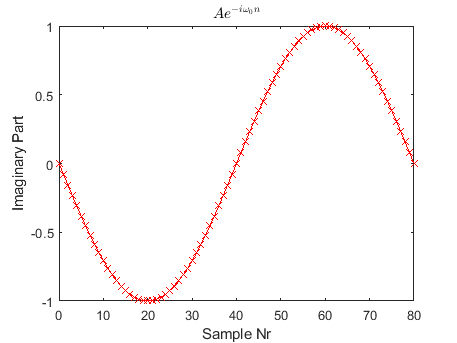


plot(n,imag(Y2),'r-x'); % imaginary part of \exp{-i\omega_0*n}
xlabel("Sample Nr");
ylabel("Imaginary Part");
title('$Ae^{-i\omega_0 n}$',"Interpreter","latex");

Finally let's calculate the Euler functions:

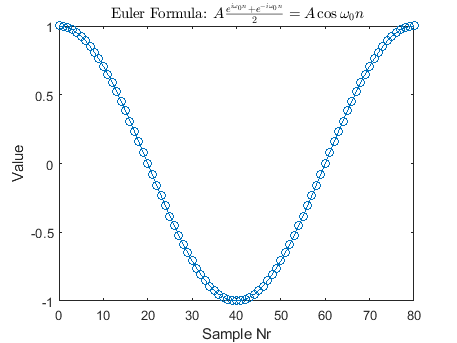


Z = (Y+Y2)/2;  % Euler formula: Z = (\exp{i\omega_0*n} + \exp{-i\omega_0*n})/2 = cos(\omega_0*n)
plot(n,Z,'-o');
xlabel("Sample Nr");
ylabel("Value");
title('Euler Formula: $A\frac{e^{i\omega_0 n}+e^{-i\omega_0 n}}{2} = A\cos{\omega_0 n}$',"Interpreter","latex");

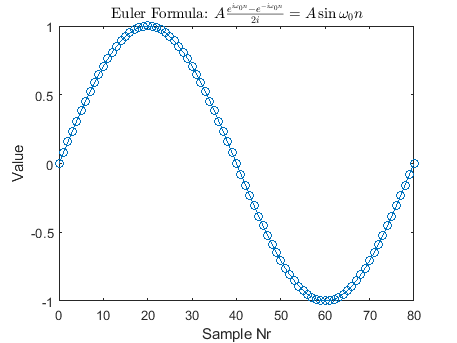


Z = (Y-Y2)/2i;  % Euler formula: Z = (\exp{i\omega_0*n} + \exp{-i\omega_0*n})/2i = sin(\omega_0*n)
plot(n,Z,'-o');
xlabel("Sample Nr");
ylabel("Value");
title('Euler Formula: $A\frac{e^{i\omega_0 n}-e^{-i\omega_0 n}}{2i} = A\sin{\omega_0 n}$',"Interpreter","latex");